# Basic example : The activity of 6 neurons during 8 seconds with firing rate at 7 Hz

    clear;

## Step 1:  Set simulation parameters

    nbNeurons = 6;     
    firingRate = 7;
    totalTime = 8;

## Step 2:  Simulate activity

    data = PoissonNeuronActivity( nbNeurons, firingRate, totalTime );

## Step 3:  Visualize the activity

First neuron

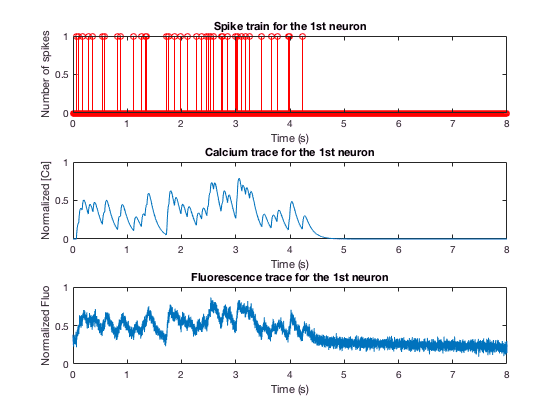

   time = data.time;
   spikeTrain = data.spikes(1,:);
   calciumTrace = data.calcium(1,:);
   fluoTrace = data.fluo(1,:);
   figure()
       subplot(3,1,1)
           stem(time,spikeTrain,'color','r');
           xlabel('Time (s)');
           ylabel('Number of spikes')
           title('Spike train for the 1st neuron');
           subplot(3,1,2)
                plot(time,calciumTrace);
                xlabel('Time (s)');
                ylabel('Normalized [Ca]')
                title('Calcium trace for the 1st neuron');
        subplot(3,1,3)
            plot(time,fluoTrace);
                xlabel('Time (s)');
                ylabel('Normalized Fluo')
                title('Fluorescence trace for the 1st neuron');

All neurons

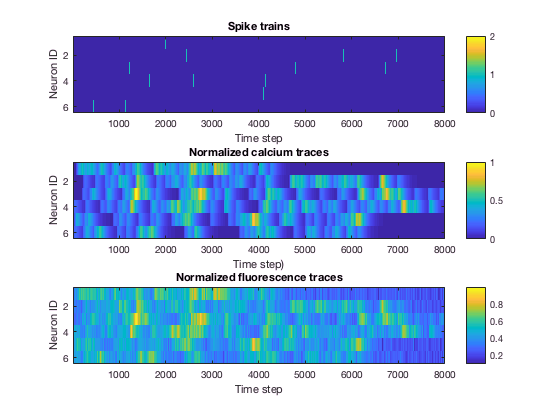

   spikeTrains = data.spikes;
   calciumTraces = data.calcium;
   fluoTraces = data.fluo;
   figure()
       subplot(3,1,1)
           imagesc(spikeTrains);colorbar;
           xlabel('Time step');
           ylabel('Neuron ID')
           title('Spike trains');
       subplot(3,1,2)
           imagesc(calciumTraces);colorbar;
           xlabel('Time step)');
           ylabel('Neuron ID')
           title('Normalized calcium traces');
        subplot(3,1,3)
           imagesc(fluoTraces);colorbar;
           xlabel('Time step');
           ylabel('Neuron ID')
           title('Normalized fluorescence traces');